%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================

clear; clc; close all;

%% ---------------- RNG ----------------
RNG_SEED = 1;
rng(RNG_SEED);

%% ---------------- USER PATHS ----------------
combinedFolder   = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matR_fallback    = fullfile(combinedFolder, 'Combined_BigResultTable.mat');

%% ---------------- SETTINGS ----------------
WAKE_BREAK_MIN   = 2;
WAKE_BREAK_SEC   = 60*WAKE_BREAK_MIN;

xmin             = 0.50;      % minutes (measurement floor)
nbinsHist        = 60;
PLOT_MIXTURE     = true;

% REMpre bin edges (minutes)
edgesRP = [0.5 5 12 71.5];

% ---------------- IQR subject outlier filter by cycle count ----------------
DO_CYCLECOUNT_IQR_FILTER = true;
IQR_MULT = 1.5;

% ---------------- EM options ----------------
opts = struct();
opts.nStarts   = 25;
opts.maxIter   = 250;
opts.tol       = 1e-7;
opts.trimFrac  = 0.01;
opts.wMin      = 0.02;
opts.wMax      = 0.98;

% E1-short bounds for r
opts.rMin      = 1e-5;
opts.rMax      = 10.0;

% TN@xmin bounds/guards
opts.sigMinTN  = 0.25;
opts.sigMaxTN  = 200.0;

% TN constraints (keep same spirit as before)
opts.MU_FLOOR_Q            = 0.10;
opts.MU_FLOOR_MIN          = xmin;      % since TN is truncated at xmin anyway
opts.ENFORCE_TN_LONG_COND  = true;
opts.Q_TN_LONG             = 0.70;
opts.LONGTAIL_QCHECK       = 0.90;
opts.LONGTAIL_MIN_MINUTES  = 25;

% ---------------- KS bootstrap ----------------
DO_KS          = false;   % true: compute KS + p-value; false: skip (faster; propensity only)
KS_B           = 1000;
KS_METHOD      = "refit"; % "plugin" or "refit"

% ---------------- Propensity ----------------
DELTA_SEC        = 30;                 % 30 s propensity window
DELTA_MIN        = DELTA_SEC/60;       % minutes
PROP_TMIN        = 0;                  % optional extra floor
TAIL_Q           = 0.995;              % tEnd from fitted quantile (full model)
DATA_TMAX_PCT    = 99.5;               % also consider data percentile
TEND_CAP_MIN     = 1000;               % hard cap (minutes)
PROP_TEND_MANUAL = 200;                % minutes (e.g., 200/600/1000). Set [] to disable.

% Peak detection stability
PEAK_SMOOTH_SEC  = 61;                 % smoothing window (seconds) for peak detection only
END_BUFFER_MIN   = 1;                  % ignore last 1 minute for peak selection (end effects)

%% ---------------- LOAD DATA (UNFILTERED) ----------------
assert(isfile(matR_fallback), 'Missing Combined_BigResultTable.mat:\n  %s', matR_fallback);
Sfb = load(matR_fallback);
assert(isfield(Sfb,'Combined_BigResultTable'), 'MAT file lacks Combined_BigResultTable.');
T = Sfb.Combined_BigResultTable;

fprintf('Loaded UNFILTERED Combined_BigResultTable:\n  %s\n', matR_fallback);

Loaded UNFILTERED Combined_BigResultTable:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\Combined_BigResultTable.mat



%% ---------------- ENSURE REQUIRED NUMERIC COLUMNS ----------------
needNum = ["REMpre","NREM","IREM","Wake","Movement"];
for v = needNum
    if ~ismember(v, string(T.Properties.VariableNames))
        T.(v) = NaN(height(T),1);
    end
    T.(v) = double(T.(v));
end

% If IREM is missing, try to reconstruct
if all(isnan(T.IREM)) && all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
    T.IREM = T.NREM + T.Wake + T.Movement;
end

%% ---------------- SUBJECT-LEVEL OUTLIER FILTER (cycle-count IQR) ----------
if DO_CYCLECOUNT_IQR_FILTER
    assert(ismember('REM_Cycle_Index', T.Properties.VariableNames), ...
        'REM_Cycle_Index column not found in table.');

    cycleID = string(T.REM_Cycle_Index);
    subjAll = extractBefore(cycleID, "_C");
    cnumAll = str2double(extractAfter(cycleID, "_C"));

    okc = isfinite(cnumAll) & cnumAll>0 & strlength(subjAll)>0;
    subjAll = subjAll(okc);
    cnumAll = cnumAll(okc);

    [G, subjList] = findgroups(subjAll);
    cyclesPerSubj = splitapply(@max, cnumAll, G);

    Q1 = prctile(cyclesPerSubj, 25);
    Q3 = prctile(cyclesPerSubj, 75);
    IQRv = Q3 - Q1;

    lowerBound = Q1 - IQR_MULT*IQRv;
    upperBound = Q3 + IQR_MULT*IQRv;

    isOut = (cyclesPerSubj < lowerBound) | (cyclesPerSubj > upperBound);
    outSubj = subjList(isOut);

    fprintf('Cycle-count IQR filter:\n');
    fprintf('  Q1=%.2f, Q3=%.2f, IQR=%.2f\n', Q1, Q3, IQRv);
    fprintf('  Bounds: [%.2f, %.2f]\n', lowerBound, upperBound);
    fprintf('  Subjects total=%d | outliers=%d\n', numel(subjList), numel(outSubj));

    if ~isempty(outSubj)
        fprintf('  Outlier subjects (by cycle count):\n');
        disp(outSubj);

        subjT = extractBefore(string(T.REM_Cycle_Index), "_C");
        dropRows = ismember(subjT, outSubj);

        nBefore = height(T);
        T = T(~dropRows, :);
        fprintf('  Dropped rows: %d | kept rows: %d (from %d)\n\n', ...
            sum(dropRows), height(T), nBefore);
    else
        fprintf('  No cycle-count outliers detected.\n\n');
    end
end

Cycle-count IQR filter:


  Q1=5.00, Q3=11.00, IQR=6.00


  Bounds: [-4.00, 20.00]


  Subjects total=573 | outliers=21


  Outlier subjects (by cycle count):


    "MNC371"
    "MNC389"
    "MNC418"
    "MNC462"
    "MNC496"
    "MNC523"
    "MNC530"
    "MNC534"
    "MNC540"
    "MNC549"
    "MNC551"
    "MNC561"
    "MNC583"
    "SC4041EC"
    "SC4042EC"
    "SC4072EH"
    "SC4291GA"
    "SC4312EM"
    "SC4611EG"
    "SC4652EG"
    "SC4762EG"



  Dropped rows: 596 | kept rows: 4426 (from 5022)




%% ---------------- IN-SCRIPT LONG-WAKE FILTER (>= WAKE_BREAK_MIN) ----------
n0 = height(T);

wakeSec = T.Wake;


if all(isnan(wakeSec))
    movSec = T.Movement;
    if all(isnan(movSec)), movSec = zeros(height(T),1); end
    if all(isfinite(T.IREM)) && all(isfinite(T.NREM))
        wakeSec = T.IREM - T.NREM - movSec;
    else
        wakeSec = NaN(height(T),1);
    end
end
wakeSec(~isfinite(wakeSec)) = NaN;

keepLW = true(height(T),1);
knownWake = isfinite(wakeSec);
keepLW(knownWake) = wakeSec(knownWake) < WAKE_BREAK_SEC;

T = T(keepLW,:);

fprintf('In-script long-wake DROP applied: Wake >= %d min (%d sec)\n', ...
    WAKE_BREAK_MIN, WAKE_BREAK_SEC);

In-script long-wake DROP applied: Wake >= 2 min (120 sec)


fprintf('  Rows before: %d | kept: %d | dropped: %d\n', n0, height(T), n0-height(T));

  Rows before: 4426 | kept: 2951 | dropped: 1475



%% ---------------- BUILD DATA (minutes) ----------------
RP_min = T.REMpre/60;
N_min  = T.NREM/60;

ok = isfinite(RP_min) & RP_min>0 & isfinite(N_min) & N_min>=xmin;
RP_min = RP_min(ok);
x      = N_min(ok);

fprintf('Valid pooled NREM cycles after LW drop and x>=%.2f: n = %d\n', xmin, numel(x));

Valid pooled NREM cycles after LW drop and x>=0.50: n = 2433



%% ========================================================================
%  LUMPED FIT: atom + (E1-short + TN@xmin) + optional KS
%==========================================================================

fitL = fit_atom_e1_tn(x, xmin, opts);

fprintf('==== LUMPED atom+ (E1-short + TN@xmin) ====\n');

==== LUMPED atom+ (E1-short + TN@xmin) ====


print_fit_console_atom(fitL);

a (atom at xmin) = 0.2922
w_cont = [0.7481 0.2519]
E1-short: r=0.108243
TN@xmin: mu=65.5715, sig=16.6277
LL=-6974.264829 | BIC=13987.51 | n=2433 | n_cont=1722


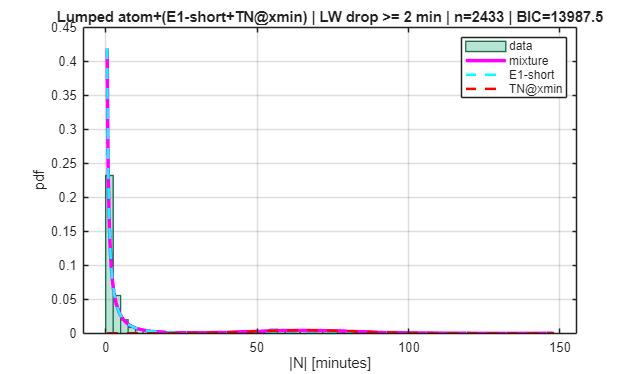


if DO_KS
    [Dobs, pval, Dnull] = ks_bootstrap_atom(x, fitL, xmin, KS_B, KS_METHOD, opts);
    fprintf('KS (%s bootstrap): D=%.6f | p=%.4g | B=%d\n', KS_METHOD, Dobs, pval, KS_B);
    fprintf('Dnull summary: min=%.4f, median=%.4f, max=%.4f\n\n', ...
        min(Dnull), median(Dnull), max(Dnull));
end

% Plot lumped histogram + model
figure('Color','w','Position',[120 120 920 540]);
face = [0.2 0.7 0.5];
edge = face*0.6;

histogram(x, nbinsHist, 'Normalization','pdf', ...
    'FaceColor',face,'FaceAlpha',0.35,'EdgeColor',edge,'LineWidth',1.0);
hold on;

xx = linspace(xmin, max(x), 900);
[yy, comps] = atom_e1tn_pdf_components(xx, fitL, xmin);

if PLOT_MIXTURE
    plot(xx, yy, 'm-', 'LineWidth',2.6);
end
plot(xx, comps(:,2), 'c--', 'LineWidth',1.9); % E1
plot(xx, comps(:,3), 'r--', 'LineWidth',1.9); % TN

grid on; box on;
xlabel('|N| [minutes]'); ylabel('pdf');
title(sprintf('Lumped atom+(E1-short+TN@xmin) | LW drop >= %d min | n=%d | BIC=%.1f', ...
    WAKE_BREAK_MIN, fitL.n, fitL.BIC), 'Interpreter','none');
legend({'data','mixture','E1-short','TN@xmin'}, 'Location','northeast');

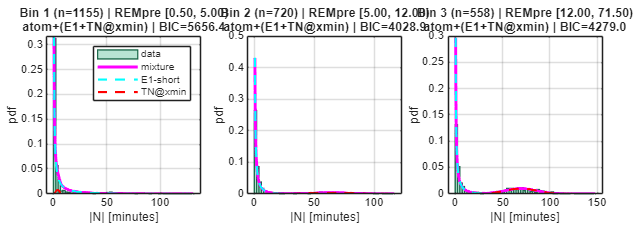

==== BIN 1 REMpre [0.50, 5.00) | n=1155 ====


a (atom at xmin) = 0.3541
w_cont = [0.9519 0.0481]
E1-short: r=0.024622
TN@xmin: mu=4.0000, sig=1.6171
LL=-2810.560414 | BIC=5656.38 | n=1155 | n_cont=746


==== BIN 2 REMpre [5.00, 12.00) | n=720 ====


a (atom at xmin) = 0.3056
w_cont = [0.7733 0.2267]
E1-short: r=0.112570
TN@xmin: mu=64.0311, sig=16.4390
LL=-1998.024071 | BIC=4028.94 | n=720 | n_cont=500


==== BIN 3 REMpre [12.00, 71.50) | n=558 ====


a (atom at xmin) = 0.1470
w_cont = [0.5231 0.4769]
E1-short: r=0.062862
TN@xmin: mu=69.4341, sig=16.2552
LL=-2123.686111 | BIC=4278.99 | n=558 | n_cont=476



%% ========================================================================
%  PER-REMpre BIN FITS + optional KS
%==========================================================================

binID = discretize(RP_min, edgesRP);
nBins = numel(edgesRP)-1;

figure('Color','w','Position',[70 80 1280 460]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

fitsB = cell(nBins,1);

for b = 1:nBins
    xb = x(binID==b);
    xb = xb(isfinite(xb) & xb>=xmin);

    nexttile;

    if numel(xb) < 80
        histogram(xb, max(10,round(numel(xb)/4)), 'Normalization','pdf', ...
            'FaceColor',face,'FaceAlpha',0.4,'EdgeColor','none');
        grid on; box on;
        xlabel('|N| [minutes]'); ylabel('pdf');
        title(sprintf('Bin %d (n=%d) | REMpre [%.2f, %.2f)', ...
            b, numel(xb), edgesRP(b), edgesRP(b+1)), 'Interpreter','none');
        continue;
    end

    fitB = fit_atom_e1_tn(xb, xmin, opts);
    fitsB{b} = fitB;

    fprintf('==== BIN %d REMpre [%.2f, %.2f) | n=%d ====\n', ...
        b, edgesRP(b), edgesRP(b+1), numel(xb));
    print_fit_console_atom(fitB);

    if DO_KS
        [Dobs, pval, Dnull] = ks_bootstrap_atom(xb, fitB, xmin, KS_B, KS_METHOD, opts);
        fprintf('KS (%s bootstrap): D=%.6f | p=%.4g | B=%d\n', KS_METHOD, Dobs, pval, KS_B);
        fprintf('Dnull summary: min=%.4f, median=%.4f, max=%.4f\n', ...
            min(Dnull), median(Dnull), max(Dnull));
    end
    fprintf('\n');

    histogram(xb, nbinsHist, 'Normalization','pdf', ...
        'FaceColor',face,'FaceAlpha',0.35,'EdgeColor',edge,'LineWidth',1.0);
    hold on;

    xxB = linspace(xmin, max(xb), 800);
    [yyB, compsB] = atom_e1tn_pdf_components(xxB, fitB, xmin);

    plot(xxB, yyB, 'm-', 'LineWidth',2.2);
    plot(xxB, compsB(:,2), 'c--', 'LineWidth',1.6);
    plot(xxB, compsB(:,3), 'r--', 'LineWidth',1.6);

    grid on; box on;
    xlabel('|N| [minutes]'); ylabel('pdf');
    title(sprintf('Bin %d (n=%d) | REMpre [%.2f, %.2f)\natom+(E1+TN@xmin) | BIC=%.1f', ...
        b, numel(xb), edgesRP(b), edgesRP(b+1), fitB.BIC), 'Interpreter','none');

    if b==1
        legend({'data','mixture','E1-short','TN@xmin'}, 'Location','northeast');
    end
end

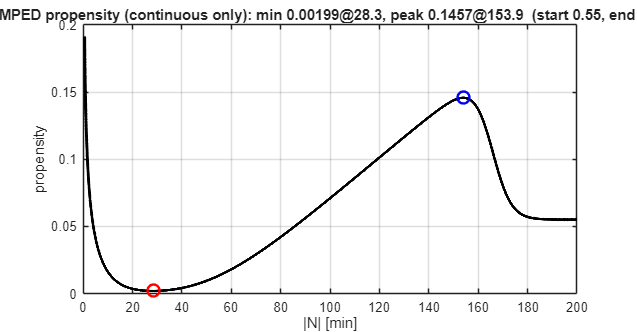


%% ========================================================================
%  LUMPED PROPENSITY PLOT (continuous component only)   
%  Fix A: start at xmin+0.05
%  1-second grid, horizon forced by PROP_TEND_MANUAL (optional)
%  Peak = MAX AFTER MIN (robust hump peak)
%==========================================================================

% Fix A: avoid spike right at xmin
tStart = max(PROP_TMIN, xmin + 0.05);

% horizon
tEnd_fit  = quantile_from_fit_atom(fitL, xmin, TAIL_Q);
tEnd_data = prctile(x, DATA_TMAX_PCT);
tEnd      = max([tStart+1, tEnd_fit, tEnd_data]);

if ~isempty(PROP_TEND_MANUAL)
    tEnd = max(tEnd, PROP_TEND_MANUAL);
end
tEnd = min(tEnd, TEND_CAP_MIN);

% 1-second grid (minutes)
nSec = floor(60*(tEnd - tStart)) + 1;
tt   = tStart + (0:(nSec-1))'/60;

prop = propensity_from_fit_atom(tt, fitL, xmin, DELTA_MIN);

% min over raw curve (for reporting)
[pmin, imin] = min(prop);
tmin = tt(imin);

% peak detection: smooth only for detection stability
propPk = movmean(prop, PEAK_SMOOTH_SEC);
[~, iminPk] = min(propPk);

% peak = maximum after minimum; ignore last END_BUFFER_MIN minutes
valid = ((1:numel(tt))' > iminPk) & (tt <= (tEnd - END_BUFFER_MIN));

if any(valid)
    [~, j] = max(propPk(valid));
    idx = find(valid);
    imax = idx(j);
else
    [~, imax] = max(propPk); 
end

% report peak on ORIGINAL curve
pmax = prop(imax);
tmax = tt(imax);

figure('Color','w','Position',[120 120 920 480]);
plot(tt, prop, 'k-', 'LineWidth',2.2); hold on;
plot(tmin, pmin, 'ro', 'MarkerSize',9, 'LineWidth',1.8);
plot(tmax, pmax, 'bo', 'MarkerSize',9, 'LineWidth',1.8);
grid on; box on;

xlabel('|N| [min]');
ylabel('propensity');

title(sprintf('LUMPED propensity (continuous only): min %.4g@%.1f, peak %.4g@%.1f  (start %.2f, end %.1f)', ...
    pmin, tmin, pmax, tmax, tStart, tEnd), 'Interpreter','none');

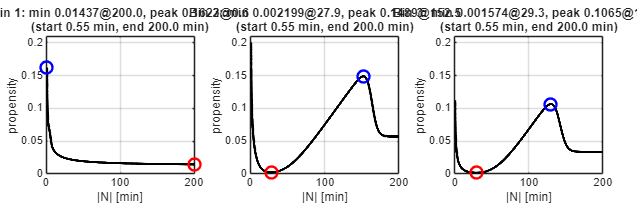


%% ========================================================================
%  PROPENSITY PLOTS (continuous component only)
%  Fix A: start at xmin+0.05
%  1-second grid, horizon forced by PROP_TEND_MANUAL (optional)
%  Peak = MAX AFTER MIN (robust hump peak)
%==========================================================================

figure('Color','w','Position',[90 120 1280 420]);
tl = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

axList = gobjects(nBins,1);
yMaxAll = 0;

for b = 1:nBins
    fitB = fitsB{b};
    ax = nexttile;
    axList(b) = ax;

    if isempty(fitB)
        axis off; title(sprintf('Bin %d: no fit', b));
        continue;
    end

    xb = x(binID==b);
    xb = xb(isfinite(xb) & xb>=xmin);

    % Fix: avoid spike right at xmin
    tStart = max(PROP_TMIN, xmin + 0.05);

    % horizon
    tEnd_fit  = quantile_from_fit_atom(fitB, xmin, TAIL_Q);
    tEnd_data = prctile(xb, DATA_TMAX_PCT);
    tEnd      = max([tStart+1, tEnd_fit, tEnd_data]);

    if ~isempty(PROP_TEND_MANUAL)
        tEnd = max(tEnd, PROP_TEND_MANUAL);
    end
    tEnd = min(tEnd, TEND_CAP_MIN);

    % 1-second grid (minutes)
    nSec = floor(60*(tEnd - tStart)) + 1;
    tt   = tStart + (0:(nSec-1))'/60;

    prop = propensity_from_fit_atom(tt, fitB, xmin, DELTA_MIN);

    % min over raw curve (for reporting)
    [pmin, imin] = min(prop);
    tmin = tt(imin);

    % peak detection: smooth only for detection stability
    propPk = movmean(prop, PEAK_SMOOTH_SEC);
    [~, iminPk] = min(propPk);

    % peak = maximum after minimum; ignore last END_BUFFER_MIN minutes
    valid = ((1:numel(tt))' > iminPk) & (tt <= (tEnd - END_BUFFER_MIN));

    if any(valid)
        [~, j] = max(propPk(valid));
        idx = find(valid);
        imax = idx(j);
    else
        [~, imax] = max(propPk); % fallback
    end

    % report peak on ORIGINAL curve
    pmax = prop(imax);
    tmax = tt(imax);

    plot(tt, prop, 'k-', 'LineWidth',2.0); hold on;
    plot(tmin, pmin, 'ro', 'MarkerSize',9, 'LineWidth',1.8);
    plot(tmax, pmax, 'bo', 'MarkerSize',9, 'LineWidth',1.8);
    grid on; box on;

    xlabel('|N| [min]');
    ylabel('propensity');

    title(sprintf('Bin %d: min %.4g@%.1f, peak %.4g@%.1f\n(start %.2f min, end %.1f min)', ...
        b, pmin, tmin, pmax, tmax, tStart, tEnd), 'Interpreter','none');

    % Track global y max for common scaling
    yMaxAll = max(yMaxAll, max(prop));
end

% Apply common y-axis limits to all visible panels
if yMaxAll > 0
    for b = 1:nBins
        if isgraphics(axList(b))
            if strcmp(get(axList(b),'Visible'),'on')
                ylim(axList(b), [0, 1.05*yMaxAll]);
            end
        end
    end
end



%% Local Functions

function print_fit_console_atom(fit)
fprintf('a (atom at xmin) = %.4f\n', fit.a);
fprintf('w_cont = [%.4f %.4f]\n', fit.w_cont(1), fit.w_cont(2));
fprintf('E1-short: r=%.6f\n', fit.r1);
fprintf('TN@xmin: mu=%.4f, sig=%.4f\n', fit.mu2, fit.sig2);
fprintf('LL=%.6f | BIC=%.2f | n=%d | n_cont=%d\n', fit.loglik(end), fit.BIC, fit.n, fit.n_cont);
end

% ======= Model: atom at xmin + continuous mixture (E1-short + TN@xmin) =====

function fit = fit_atom_e1_tn(x, xmin, opts)
x = x(:);
x = x(isfinite(x) & x>=xmin);
n = numel(x);

isAtom = (abs(x - xmin) < 1e-12);
a = mean(isAtom);

xcont = x(~isAtom);
ncont = numel(xcont);

% If everything is atom, bail safely
if ncont < 10
    fit = struct('a',a,'w_cont',[0.5 0.5],'r1',0.1,'mu2',xmin+1,'sig2',10, ...
        'loglik',-inf,'BIC',inf,'n',n,'n_cont',ncont);
    return;
end

bestLL = -inf;
best = [];

% init r from rough scale of xcont (small r => heavier tail)
r0 = clamp(1/max(mean(xcont),1), opts.rMin, opts.rMax);

% init TN near upper-middle
mu0  = max(quantile(xcont, 0.75), xmin+0.1);
sig0 = clamp(0.5*iqr(xcont), opts.sigMinTN, opts.sigMaxTN);
if ~isfinite(sig0) || sig0<=0
    sig0 = clamp(std(xcont), opts.sigMinTN, opts.sigMaxTN);
end

for s = 1:opts.nStarts
    w = rand(1,2); w = w/sum(w);
    w = clamp_weights2(w, opts);

    r1   = clamp(r0*(0.5 + 1.5*rand), opts.rMin, opts.rMax);
    mu2  = clamp(mu0*(0.8 + 0.8*rand), xmin, max(xcont));
    sig2 = clamp(sig0*(0.6 + 1.2*rand), opts.sigMinTN, opts.sigMaxTN);

    [w,r1,mu2,sig2,LL] = em2_e1_tn_cont(xcont, xmin, w, r1, mu2, sig2, opts);

    if LL(end) > bestLL
        bestLL = LL(end);
        best = {w,r1,mu2,sig2,LL};
    end
end

[w,r1,mu2,sig2,LL] = best{:};

% Total log-likelihood includes:
%   - atom mass: a^nAtom * (1-a)^nCont (binomial piece)
%   - continuous likelihood on xcont under mixture density
nAtom = sum(isAtom);
LL_atom = nAtom*log(max(a,realmin)) + ncont*log(max(1-a,realmin));
LL_total = LL_atom + LL(end);

% BIC params: a(1) + w(1 free) + r(1) + TN(2) = 5
kpar = 5;
BIC  = -2*LL_total + kpar*log(n);

fit = struct('a',a,'w_cont',w,'r1',r1,'mu2',mu2,'sig2',sig2, ...
    'loglik', [LL_total], 'BIC',BIC,'n',n,'n_cont',ncont);
end

function [w,r1,mu2,sig2,LL] = em2_e1_tn_cont(x, xmin, w, r1, mu2, sig2, opts)
x = x(:);
n = numel(x);
LL = zeros(opts.maxIter,1);
trimN = floor(opts.trimFrac*n);

for it = 1:opts.maxIter
    p1 = w(1) * e1_pdf(x, xmin, r1);
    p2 = w(2) * tnorm_pdf_xmin(x, xmin, mu2, sig2);
    s  = p1 + p2;

    r1post = p1 ./ max(s, eps);
    r2post = p2 ./ max(s, eps);

    keep = true(n,1);
    if trimN > 0
        [~,idx] = sort(s,'ascend');
        keep(idx(1:trimN)) = false;
    end

    xk  = x(keep);
    z1k = r1post(keep);
    z2k = r2post(keep);

    % weights
    w = [mean(z1k), mean(z2k)];
    w = clamp_weights2(w, opts);

    % E1-short: weighted MLE for r via 1D fminsearch
    r1 = e1_wmle_r(xk, xmin, z1k, r1, opts);

    % TN@xmin: weighted MLE via fminsearch
    [mu2, sig2] = tnorm_wmle_xmin_fminsearch(xk, xmin, z2k, mu2, sig2, opts);

    % constraints
    muFloor = max(opts.MU_FLOOR_MIN, quantile(xk, opts.MU_FLOOR_Q));
    mu2 = max(mu2, muFloor);

    if opts.ENFORCE_TN_LONG_COND
        qcheck = quantile(xk, opts.LONGTAIL_QCHECK);
        if qcheck >= opts.LONGTAIL_MIN_MINUTES
            mu2 = max(mu2, quantile(xk, opts.Q_TN_LONG));
        end
    end

    sig2 = clamp(sig2, opts.sigMinTN, opts.sigMaxTN);

    % LL on kept
    p1k = w(1) * e1_pdf(xk, xmin, r1);
    p2k = w(2) * tnorm_pdf_xmin(xk, xmin, mu2, sig2);
    LL(it) = sum(log(max(p1k+p2k, eps)));

    if it>1 && abs(LL(it)-LL(it-1)) < opts.tol*max(1,abs(LL(it-1)))
        LL = LL(1:it);
        break;
    end
end

LL = LL(1:it);
end

% ------------------- PDF components for plotting (atom is point mass) -----
function [yy, comps] = atom_e1tn_pdf_components(xx, fit, xmin)
xx = xx(:);
comps = zeros(numel(xx),3);

comps(:,1) = 0; % atom is point mass

pE1 = e1_pdf(xx, xmin, fit.r1);
pTN = tnorm_pdf_xmin(xx, xmin, fit.mu2, fit.sig2);

comps(:,2) = (1-fit.a) * fit.w_cont(1) * pE1;
comps(:,3) = (1-fit.a) * fit.w_cont(2) * pTN;

yy = sum(comps,2);
yy(xx < xmin) = 0;
end

% ------------------- CDF of full model -----------------------------------
function F = cdf_atom_model(t, fit, xmin)
t = t(:);
F = zeros(size(t));

below = (t < xmin);
F(below) = 0;

ta = t(~below);

Fatom = fit.a * ones(size(ta));
Fc = fit.w_cont(1)*e1_cdf(ta, xmin, fit.r1) + fit.w_cont(2)*tnorm_cdf_xmin(ta, xmin, fit.mu2, fit.sig2);

F(~below) = Fatom + (1-fit.a)*Fc;
F = min(max(F,0),1);
end

% ------------------- CDF of continuous component only ---------------------
function Fc = cdf_cont_only(t, fit, xmin)
t = t(:);
Fc = zeros(size(t));
below = (t < xmin);
Fc(below) = 0;
ta = t(~below);
Fc(~below) = fit.w_cont(1)*e1_cdf(ta, xmin, fit.r1) + fit.w_cont(2)*tnorm_cdf_xmin(ta, xmin, fit.mu2, fit.sig2);
Fc = min(max(Fc,0),1);
end

% ------------------- Propensity from continuous component -----------------
% pΔ(t) = P(T in [t, t+Δ) | T >= t) = (Fc(t+Δ)-Fc(t)) / (1-Fc(t))
function p = propensity_from_fit_atom(tt, fit, xmin, delta)
tt = tt(:);
Fc_t   = cdf_cont_only(tt, fit, xmin);
Fc_tp  = cdf_cont_only(tt + delta, fit, xmin);
num = max(Fc_tp - Fc_t, 0);
den = max(1 - Fc_t, realmin);
p = num ./ den;
p(~isfinite(p)) = 0;
end

% ------------------- Quantile from full fit (bisection) -------------------
function q = quantile_from_fit_atom(fit, xmin, prob)
prob = min(max(prob, 1e-6), 1-1e-6);

lo = xmin;
hi = max(xmin+1, fit.mu2 + 8*fit.sig2);
for k = 1:60
    if cdf_atom_model(hi, fit, xmin) >= prob, break; end
    hi = hi*1.5;
end

for it = 1:70
    mid = 0.5*(lo+hi);
    if cdf_atom_model(mid, fit, xmin) < prob
        lo = mid;
    else
        hi = mid;
    end
end
q = 0.5*(lo+hi);
end

%% ======================= KS via bootstrap ===============================

function [Dobs, pval, Dnull] = ks_bootstrap_atom(x, fit, xmin, B, method, opts)
x = x(:);
x = x(isfinite(x) & x>=xmin);
n = numel(x);

Dobs = ks_distance_emp_vs_cdf(x, @(t) cdf_atom_model(t, fit, xmin));
Dnull = zeros(B,1);

for b = 1:B
    xb = sample_from_fit_atom(n, fit, xmin);

    if method == "plugin"
        Dnull(b) = ks_distance_emp_vs_cdf(xb, @(t) cdf_atom_model(t, fit, xmin));
    else
        fitb = fit_atom_e1_tn(xb, xmin, opts);
        Dnull(b) = ks_distance_emp_vs_cdf(xb, @(t) cdf_atom_model(t, fitb, xmin));
    end
end

pval = mean(Dnull >= Dobs);
end

function D = ks_distance_emp_vs_cdf(x, cdfFun)
x = sort(x(:));
n = numel(x);
F = cdfFun(x);
Fn = (1:n)'/n;
D = max(abs(Fn - F));
end

function xs = sample_from_fit_atom(n, fit, xmin)
u = rand(n,1);
xs = zeros(n,1);

isAtom = (u < fit.a);
xs(isAtom) = xmin;

ncont = sum(~isAtom);
if ncont==0, return; end

u2 = rand(ncont,1);
isE1 = (u2 < fit.w_cont(1));

ne1 = sum(isE1);
ntn = ncont - ne1;

xcont = zeros(ncont,1);
if ne1 > 0
    xcont(isE1) = e1_rnd(ne1, xmin, fit.r1);
end
if ntn > 0
    xcont(~isE1) = tnorm_rnd_xmin(ntn, xmin, fit.mu2, fit.sig2);
end

xs(~isAtom) = xcont;
end

%% ======================= E1-short distribution ==========================
% pdf on [xmin,inf):  f(t) = exp(-r t) / ( t * E1(r*xmin) )

function y = e1_pdf(t, xmin, r)
t = t(:);
y = zeros(size(t));
ix = (t >= xmin);
Z = max(expint(r*xmin), realmin);
y(ix) = exp(-r*t(ix)) ./ (t(ix) * Z);
y(~isfinite(y)) = 0;
end

function F = e1_cdf(t, xmin, r)
t = t(:);
F = zeros(size(t));
ix = (t >= xmin);
Z = max(expint(r*xmin), realmin);
F(ix) = 1 - expint(r*t(ix)) ./ Z;
F = min(max(F,0),1);
end

function rHat = e1_wmle_r(x, xmin, w, r0, opts)
x = x(:); w = max(w(:),0);
if sum(w) < eps
    rHat = r0; return;
end

p0 = log(max(r0, opts.rMin));
obj = @(p) e1_negwll_r(exp(p), x, xmin, w, opts);

p = fminsearch(obj, p0, optimset('Display','off','MaxIter',300,'TolX',1e-6,'TolFun',1e-6));
rHat = exp(p);
rHat = clamp(rHat, opts.rMin, opts.rMax);
end

function val = e1_negwll_r(r, x, xmin, w, opts)
r = clamp(r, opts.rMin, opts.rMax);
Z = max(expint(r*xmin), realmin);
logpdf = -r*x - log(max(x,realmin)) - log(Z);
val = -sum(w .* logpdf);
if ~isfinite(val), val = realmax; end
end

function t = e1_rnd(n, xmin, r)
u = rand(n,1);
Z = max(expint(r*xmin), realmin);
target = (1-u)*Z;

t = zeros(n,1);
for i=1:n
    lo = xmin;
    hi = max(xmin+1, xmin*2);
    for k=1:60
        if expint(r*hi) <= target(i), break; end
        hi = hi*1.5;
    end
    for it=1:60
        mid = 0.5*(lo+hi);
        if expint(r*mid) > target(i)
            lo = mid;
        else
            hi = mid;
        end
    end
    t(i) = 0.5*(lo+hi);
end
end

%% ======================= Truncated Normal on [xmin,inf) ==================
function y = tnorm_pdf_xmin(x, xmin, mu, sig)
x = x(:);
sig = max(sig, realmin);

a = (xmin - mu)/sig;
Z = 1 - normcdf0(a);
Z = max(Z, realmin);

y = zeros(size(x));
ix = (x >= xmin);
z = (x(ix)-mu)/sig;
y(ix) = (normpdf0(z)./sig) ./ Z;
y(~isfinite(y)) = 0;
end

function F = tnorm_cdf_xmin(x, xmin, mu, sig)
x = x(:);
sig = max(sig, realmin);

a = (xmin - mu)/sig;
Fa = normcdf0(a);
Z  = 1 - Fa;
Z  = max(Z, realmin);

F = zeros(size(x));
ix = (x >= xmin);
z = (x(ix)-mu)/sig;
F(ix) = (normcdf0(z) - Fa) ./ Z;
F = min(max(F,0),1);
end

function [muHat, sigHat] = tnorm_wmle_xmin_fminsearch(x, xmin, r, mu0, sig0, opts)
x = x(:); r = max(r(:),0);
den = max(sum(r), eps);
if den <= 0
    muHat = mu0; sigHat = sig0; return;
end

m = sum(r.*x)/den;
v = sum(r.*(x-m).^2)/den;

mu0 = max(mu0, xmin);
sig0 = clamp(max(sig0, sqrt(max(v,1e-6))), opts.sigMinTN, opts.sigMaxTN);

p0 = [mu0, log(sig0)];
obj = @(p) tnorm_negwll_xmin(p, x, xmin, r, opts);

p = fminsearch(obj, p0, optimset('Display','off','MaxIter',300,'TolX',1e-6,'TolFun',1e-6));

muHat  = max(p(1), xmin);
sigHat = exp(p(2));
sigHat = clamp(sigHat, opts.sigMinTN, opts.sigMaxTN);
end

function val = tnorm_negwll_xmin(p, x, xmin, r, opts)
mu  = max(p(1), xmin);
sig = exp(p(2));
sig = clamp(sig, opts.sigMinTN, opts.sigMaxTN);

a  = (xmin - mu)/sig;
Fa = normcdf0(a);
Z  = 1 - Fa;
Z  = max(Z, realmin);

z = (x - mu)/sig;
logpdf = log(normpdf0(z)./sig) - log(Z);

bad = (x < xmin | ~isfinite(logpdf));
logpdf(bad) = -1e6;

val = -sum(r .* logpdf);
if ~isfinite(val), val = realmax; end
end

function x = tnorm_rnd_xmin(n, xmin, mu, sig)
x = zeros(n,1);
k = 0;
while k < n
    m = max(200, n-k);
    z = mu + sig*randn(m,1);
    z = z(z >= xmin);
    take = min(numel(z), n-k);
    if take > 0
        x(k+1:k+take) = z(1:take);
        k = k + take;
    end
end
end

%% ======================= Normal helpers (toolbox-free) ===================
function y = normpdf0(z)
y = exp(-0.5*z.^2) / sqrt(2*pi);
end

function F = normcdf0(z)
F = 0.5*(1 + erf(z./sqrt(2)));
end

%% ======================= Utilities ======================================
function w = clamp_weights2(w, opts)
w = max(w, opts.wMin);
w = w / sum(w);
w = min(max(w, opts.wMin), opts.wMax);
w = w / sum(w);
end

function y = clamp(x, lo, hi)
y = min(max(x, lo), hi);
end
